clear; clc; close all; fclose('all');

**OFDM Parameters**

nfft = 1024;                    % nfft size equal to number of subcarriers
BW = 1000000000;                % Bandwidth of subcarriers (-F/2 F/2)
M = 128;                        % Baseband modulation order
cp_len = nfft/4;                % Cyclic Prefix length
ofdm_symbols = 3;               % Number of ofdm symbols to transmit
rep = 4;                        %   Repetition of pilots
pilot_index = 112:rep:913;      % Insert a pilot every 3 data sub-carriers
data_index = 1:nfft;            % Index of data subcarriers
snr = 30;                       % Signal to noise ratio

% Set 224 zero padded subcarriers: 111 on lower and upper subcarriers
% and 2 on each side of carrier
zp_index = [1:111,913:1024];
no_multi = [1 0 0 0 0 0 0 0];
%multipath = [0 0 0 0 0 0.3 0.9 0.4];
multipath = [0 1 0.5 0 0 0 1];
%multipath = [1 0 0 0 0 0 0];
cpo = pi/2;
freq_avg = 50;
time_avg = 1;

pilot_carriers = length(pilot_index);
data_index([zp_index,pilot_index]) = [];
data_carriers = length(data_index);
scs = BW/nfft;
plot_v = 0;
scale = 2.6e3;
plot_length = 1:pilot_carriers*ofdm_symbols;
plot_length_data = 1:data_carriers+pilot_carriers*ofdm_symbols;
num_data_bits = length(data_index)*ofdm_symbols

num_data_bits = 1800

file = fopen('../../../HW/modules/sim/zf_equalizer/info.txt','wt');
fprintf(file,"%d",ofdm_symbols);

**Modulate:**

[ofdm_signal,P1,mod_data,t,t2,freq_signal]=ofdm_transmit(nfft,BW,M,cp_len, ...
    ofdm_symbols,zp_index,pilot_index,0,1);

**Channel:**

ofdm_signal_rx = awgn(ofdm_signal,snr,'measured');
ofdm_signal_rx = filter(multipath,1,ofdm_signal_rx);

**Demodulate:**

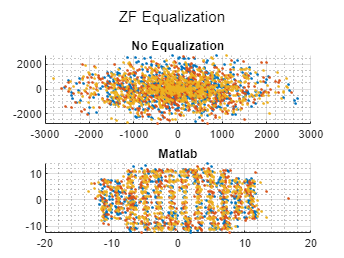

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Serial to Parallel
ofdm_signal_par = reshape(ofdm_signal_rx,[nfft+cp_len ofdm_symbols]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CFO Correction
cp_rm = ofdm_signal_par;
cp_rm(1:cp_len,:) = [];
ofdm_cfo_signal_par_eq = [];
cfo_est = 0;
for i = 1:ofdm_symbols
    cp_cfo_begin = ofdm_signal_par(1:cp_len,i);             % Obtain cyclic prefix at beginning of symbol
    cp_cfo_end = (ofdm_signal_par(nfft+1:end,i));       % Obtain cyclic prefix at end of symbol
    %cp_cfo_est = filter(cp_cfo_end,1,cp_cfo_begin);             % Correlate 
    tmp = cp_cfo_end.*conj(cp_cfo_begin);
    mult_val = complex(real(cp_cfo_end.*conj(cp_cfo_begin)),imag(cp_cfo_end.*conj(cp_cfo_begin)));
    sum_val = sum(mult_val);
    tan_val = atan2(imag(sum_val),real(sum_val));
    normalized_cfo_est = 1*tan_val;
    %normalized_cfo_est = 1/2/pi*angle(sum_val);
    %cfo_est = cfo_est + normalized_cfo_est * scs;
    cfo_est = normalized_cfo_est * scs;
    %ofdm_cfo_signal_par_eq(:,i) = cp_rm(:,i).*exp(1i*cfo_est*t(1:nfft))';
    ofdm_cfo_signal_par_eq(:,i) = cp_rm(:,i).*(cos(cfo_est*t(1:nfft))+1i*sin(cfo_est*t(1:nfft)))';
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FFT
fft_out_cfo = fft(ofdm_cfo_signal_par_eq,nfft);
fft_out_cfo = round(1e2*fft_out_cfo);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Obtain Pilots
P_RX = fft_out_cfo(pilot_index,:);
num = conj(P_RX); denom = conj(P1); 
num_abs = abs(num); num_ang = angle(num); denom_abs = abs(denom); denom_ang = angle(denom);
H_ang = num_ang - denom_ang;
H_abs = num_abs ./ denom_abs;
H = H_abs .* exp(-1i*H_ang);
H = num ./ denom;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Normal ZF equalization
H_ZF_interp = interp1(pilot_index,H,1:nfft,'nearest');
Z_EQ_ZF = fft_out_cfo ./ conj(H_ZF_interp);
Z_EQ_ZF([pilot_index,zp_index],:) = [];
figure(),subplot(2,1,1),scatter(real(fft_out_cfo),imag(fft_out_cfo),'.','LineWidth',2),grid on,grid minor,title('No Equalization')
subplot(2,1,2),scatter(real(Z_EQ_ZF),imag(Z_EQ_ZF),'.','LineWidth',2),grid on,grid minor,title('Matlab')
sgtitle('ZF Equalization')